% b) Defina, em Matlab, a correspondente matriz de transic¸ ˜ao;
T = [.7 .2 .3
     .2 .3 .3
     .1 .5 .4];

% Posições na matriz
SOL = 1

SOL = 1

NUVENS = 2

NUVENS = 2

CHUVA = 3

CHUVA = 3

## c

% (c) Assumindo que a observac¸ ˜ao inicial (digamos no dia 0) ´e que o dia ´e de sol, qual a probabilidade
% do dia 2 ser de chuva ?

v = [1;0;0];
v2 = T^2*v;
resp = v2(CHUVA);

fprintf("%.3f\n",resp);

0.210


## d

% (d) Calcule as n primeiras potˆencias de T (n=20) e apresente num gr´afico a evoluc¸ ˜ao dos v´arios ele-
% mentos da matriz em func¸ ˜ao de n;
n = 20

n = 20


M = T(:);

for i = 2:n

    aux = T^i;
    M = [M aux(:)];

end

M

M =     0.7000    0.5600    0.5010    0.4760    0.4654    0.4609    0.4590    0.4582    0.4579    0.4577    0.4577    0.4576    0.4576    0.4576    0.4576    0.4576    0.4576    0.4576    0.4576    0.4576
    0.2000    0.2300    0.2440    0.2499    0.2524    0.2535    0.2539    0.2541    0.2542    0.2542    0.2542    0.2542    0.2542    0.2542    0.2542    0.2542    0.2542    0.2542    0.2542    0.2542
    0.1000    0.2100    0.2550    0.2741    0.2822    0.2856    0.2871    0.2877    0.2879    0.2881    0.2881    0.2881    0.2881    0.2881    0.2881    0.2881    0.2881    0.2881    0.2881    0.2881
    0.2000    0.3500    0.4120    0.4383    0.4494    0.4542    0.4562    0.4570    0.4574    0.4575    0.4576    0.4576    0.4576    0.4576    0.4576    0.4576    0.4576    0.4576    0.4576    0.4576
    0.3000    0.2800    0.2650    0.2588    0.2562    0.2551    0.2546    0.2544    0.2543    0.2543    0.2542    0.2542    0.2542    0.2542    0.2542    0.2542    0.2542    0.2542    0.2542  

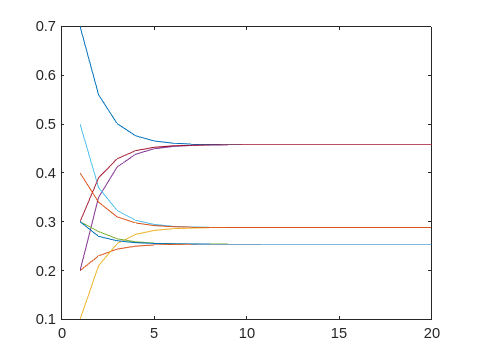

plot(M')

## e

% (e) Repita o processo da al´ınea anterior parando-o assim que o m´aximo do m´odulo da diferenc¸a entre
% os valores dos elementos da matriz em duas iterac¸ ˜oes consecutivas n˜ao exceda 10−4;

previous = T;

while 1
    %iter n
    %iter n+1
    n1 = T* previous;
   
    %diferença
    dif = max(max(abs(n1-previous)));
    
    % se dif < limiar
    % END

    if dif < 1e-16
        break
    end

    % atualizar o previous
    previous = n1;
end


## f

% (f) Confirme o valor obtido na al´ınea anterior, calculando o vetor estado em regime estacion´ario usando
% um m´etodo n˜ao iterativo.
M = [T - eye(3); ones(1,3)];

b = [zeros(3,1); 1];

u = M\b;



## 2

## a

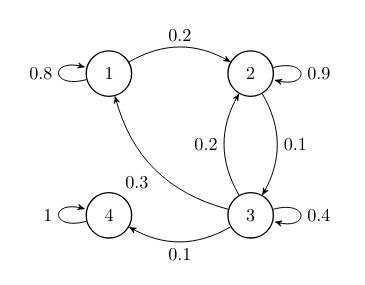

% (a) Escreva a matriz de transic¸ ˜ao H (de Hyperlinks), com Hji sendo a probabilidade de ir da p´agina i
% para a p´agina j num ´unico passo. Crie em Matlab essa matriz
H = [.8 .2 0 0
     0 .9 .1 0
     .3 .2 .4 .1
     0 0 0 1];


## b

% (b) Qual a probabilidade de comec¸ando na p´agina 1 ao fim de 1000 passos estar na p´agina 2? Estava `a
% espera deste valor?
v = [1 0 0 0]';

res = H^1000*v;

res(2)

ans = 1.3212e-06

ou

H1000 = H^1000

H1000 =     0.0000    0.0000    0.0000    1.0000
    0.0000    0.0000    0.0000    1.0000
    0.0000    0.0000    0.0000    1.0000
         0         0         0    1.0000


res = H1000(2,1)

res = 1.3212e-06

## c

% (c) Determine a probabilidade de chegar `a p´agina j a partir da p´agina i, em 1,2,10 e 100 passos.

T^10

ans =     0.4577    0.4575    0.4576
    0.2542    0.2543    0.2543
    0.2881    0.2882    0.2882


T^1000

ans =     0.4576    0.4576    0.4576
    0.2542    0.2542    0.2542
    0.2881    0.2881    0.2881


## d

% (d) Determine a matriz Q.

num_estados_nao_absorventes = 3;
Q = H(1:num_estados_nao_absorventes,1:num_estados_nao_absorventes)

Q =     0.8000    0.2000         0
         0    0.9000    0.1000
    0.3000    0.2000    0.4000


## e

% (e) Determine a matriz fundamental F .
F = inv(eye(num_estados_nao_absorventes) - Q)'

F =    20.0000   15.0000   15.0000
   60.0000   60.0000   50.0000
   10.0000   10.0000   10.0000




% nº de vezes que se passa em cada ppagina, começando em 1, 2, oou 3

## f

% (f) Qual a m´edia (valor esperado) do n´umero de passos necess´arios para atingir a p´agina 4 comec¸ando
% na p´agina 1? e se comec¸armos na p´agina 2? e se iniciarmos na p´agina 3?

sum(F)

ans =    90.0000   85.0000   75.0000



% primeiro valor para a primeira págna, 2º valor para a 2ª página, 3 valor
% para a 3 pagina

## g

% (g) Qual o tempo at´e `a absorc¸ ˜ao das p´aginas 1 a 3?
one = ones(3,1);
T = F'*one

T =    90.0000
   85.0000
   75.0000


## 3

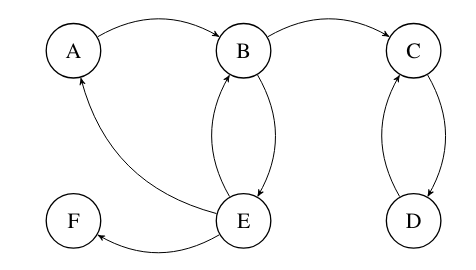

## a) 

% (a) Usando a matriz H das hiperligac¸ ˜oes, obtenha a estimativa do pagerank de cada p´agina ao fim de
% 10 iterac¸ ˜oes. Relembre que deve considerar (i) a mesma probabilidade de transic¸ ˜ao de cada p´agina
% para todas as p´aginas seguintes poss´ıveis e (ii) a probabilidade da p´agina inicial deve ser igual para
% todas as p´aginas. Qual/quais a(s) p´agina(s) com maior pagerank e qual o seu valor˜?

N = 6;
A = 1, B = 2, C = 3, D = 4, E = 5, F = 6

A = 1

B = 2

C = 3

D = 4

E = 5

F = 6

H = zeros(N);

H(B,A) = 1;
H(C,B) = 1;
H(E,B) = 1;
H(D,C) = 1;
H(C,D) = 1;
H(A,E) = 1;
H(B,E) = 1;
H(F,E) = 1;

saidas = sum(H);
H = H ./ saidas;
H(isnan(H)) = 0;
H

H =          0         0         0         0    0.3333         0
    1.0000         0         0         0    0.3333         0
         0    0.5000         0    1.0000         0         0
         0         0    1.0000         0         0         0
         0    0.5000         0         0         0         0
         0         0         0         0    0.3333         0


## b

% o dead end é o F
% a spider trap é entre C e D


## c

% (c) Altere a matriz H para resolver apenas o problema do ”dead-end” e recalcule o pagerank de cada
% p´agina novamente em 10 iterac¸ ˜oes.


H = H .* saidas;
H(A,F) = 1;
H(B,F) = 1;
H(C,F) = 1;
H(D,F) = 1;
H(E,F) = 1;
H(F,F) = 1;
saidas = sum(H);
H = H ./ saidas

H =          0         0         0         0    0.3333    0.1667
    1.0000         0         0         0    0.3333    0.1667
         0    0.5000         0    1.0000         0    0.1667
         0         0    1.0000         0         0    0.1667
         0    0.5000         0         0         0    0.1667
         0         0         0         0    0.3333    0.1667



n = 6;
v0 = ones(1,n) / n

v0 =     0.1667    0.1667    0.1667    0.1667    0.1667    0.1667


v0 = v0';
v10 = H^10 * v0

v10 =     0.0066
    0.0154
    0.4821
    0.4777
    0.0117
    0.0066


## d

% (d) Resolva agora ambos os problemas e recalcule o pagerank de cada p´agina novamente em 10
% iterac¸ ˜oes (assuma β = 0, 8).

H = H .* saidas;
H(A,F) = 0;
H(B,F) = 0;
H(C,F) = 0;
H(D,F) = 0;
H(E,F) = 0;
saidas = sum(H);
H = H ./ saidas

H =          0         0         0         0    0.3333         0
    1.0000         0         0         0    0.3333         0
         0    0.5000         0    1.0000         0         0
         0         0    1.0000         0         0         0
         0    0.5000         0         0         0         0
         0         0         0         0    0.3333    1.0000



beta = 0.8

beta = 0.8000

n = 6;
v0 = ones(n) / n;
v01 = ones(1,n) / n;
v01 = v01';
A = beta * H + (1-beta) * v0

A =     0.0333    0.0333    0.0333    0.0333    0.3000    0.0333
    0.8333    0.0333    0.0333    0.0333    0.3000    0.0333
    0.0333    0.4333    0.0333    0.8333    0.0333    0.0333
    0.0333    0.0333    0.8333    0.0333    0.0333    0.0333
    0.0333    0.4333    0.0333    0.0333    0.0333    0.0333
    0.0333    0.0333    0.0333    0.0333    0.3000    0.8333


a10 = A^10 * v01

a10 =     0.0523
    0.0943
    0.2711
    0.2501
    0.0711
    0.2611


ans = 1

## e